## **Week 8**

Questions from book chapter

13.9 What are the basic properties of the cumulative distribution function?


$$0 \leq F(x) \leq 1, for\ all \ x$$


13.13 What quality of a random variable is described by the mean? What by the variance?

***Mean:**** descibes the center of a propability distribution i.e. the average value variable*

***Variance: ****a measure of the spread or dispersion of a distribution around its mean value.*

13.22 When two variables are uncorrelated they are also statistically independent? true/false

*False, not all uncorrelated variables are also independent. If they're independent, then they're also uncorrelated.*

### Problem 4.1

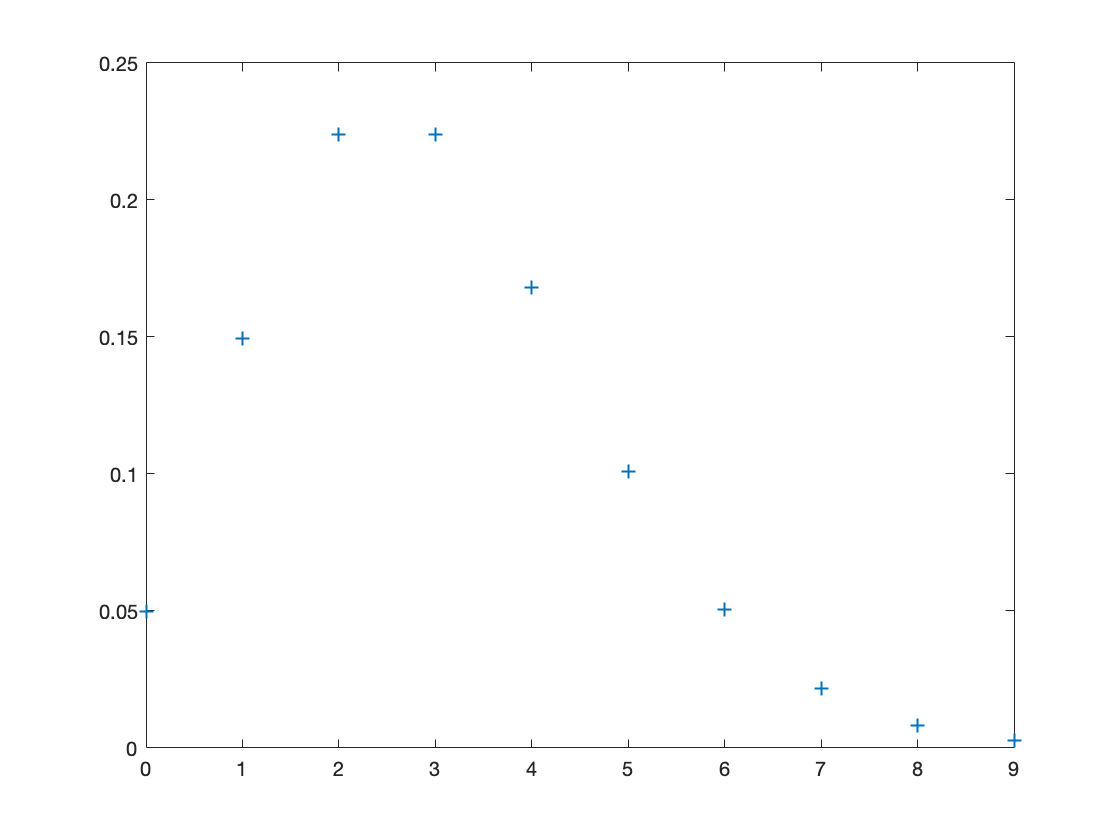

a = 3;
x = 0:9;
y = poisspdf(x,a);
plot(x,y,'+')

Pr4 = PoissonPr(a,4);

p = 0.1680

Pr5 = PoissonPr(a,5);

p = 0.1008

Pr4_5 = Pr4 + Pr5

Pr4_5 = 0.2689

PrG3 = 1-(PoissonPr(a,0)+PoissonPr(a,1)+PoissonPr(a,2))

p = 0.0498

p = 0.1494

p = 0.2240

PrG3 = 0.5768

### Problem 4.3

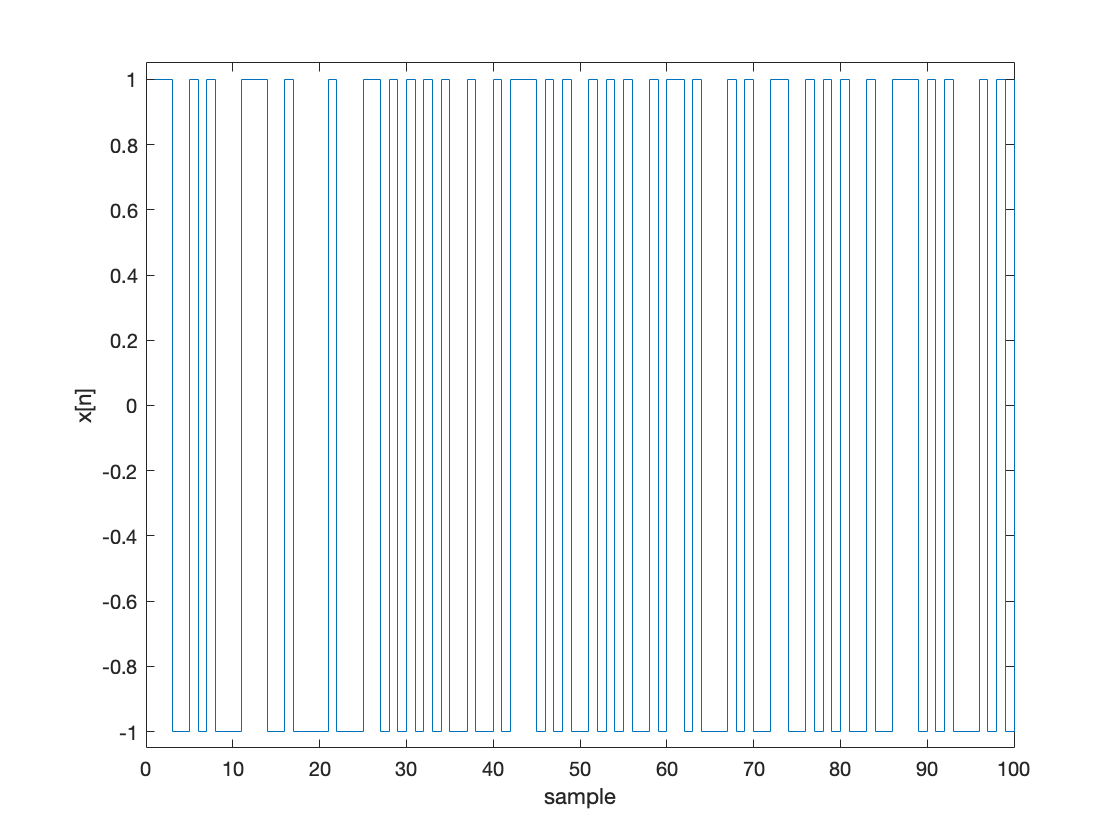

N=100;
x=zeros(N,1);

%% equal probability of -1 or 1 in x(1)
if randn(1) >= 0
    x(1)=1;
else
    x(1)=-1;
end

%% change sign with 75% probability
for n=2:N
    if rand(1)<0.75
        x(n)=-x(n-1);
    else
        x(n)=x(n-1);
    end
end

%% plot result

stairs(x)
ylim([-1.05 1.05])
xlabel('sample')
ylabel('x[n]')

function p = PoissonPr(a, k)
p = ((a^k)*exp(-a)/(factorial(k)))  
end